# Funcions de diverses variables

## Normes i/o distàncies entre vectors

format short g
x = [0 -1 1 3 -0.1 10];
norm(x)          % norma 2

ans =        10.536


norm(x, 1)       % norma 1

ans =          15.1


norm(x, 'inf')   % norma infinit

ans =     10


## Normes i/o distàncies entre matrius

A = hilb(5)     % matriu hilbert

A =             1          0.5      0.33333         0.25          0.2
          0.5      0.33333         0.25          0.2      0.16667
      0.33333         0.25          0.2      0.16667      0.14286
         0.25          0.2      0.16667      0.14286        0.125
          0.2      0.16667      0.14286        0.125      0.11111


%format rat; A 
%format shortG
norm(A)         % norma  compatible amb norma 2 vectorial

ans =        1.5671


sqrt(eig(A'*A))

ans =    3.2879e-06
    0.0003059
     0.011407
      0.20853
       1.5671


norm(A, 1), norm(A, 'inf')  %norma 1 = suma de primera columna de A, norma2 = suma e prima columna de A'

ans =        2.2833


ans =        2.2833


sum(A), sum(A') 

ans =        2.2833         1.45       1.0929      0.88452      0.74563


ans =        2.2833         1.45       1.0929      0.88452      0.74563


norm(A, 'fro')

ans =        1.5809


## Funcions 2 variables

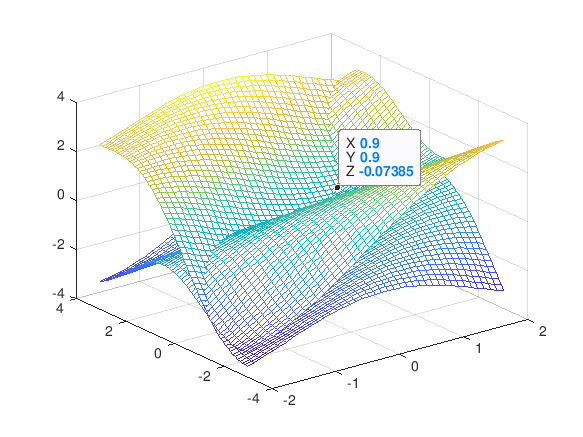

F1 = @(x,y)x-sin(x+y);
F2 = @(x,y)y-cos(x-y);
x=-2:0.1:2;
y=-3:0.1:3;
[X, Y] = meshgrid(x,y);
Z1 = F1(X,Y); Z2 = F2(X,Y);
mesh(X,Y,Z1)
hold on
mesh(X,Y,Z2)